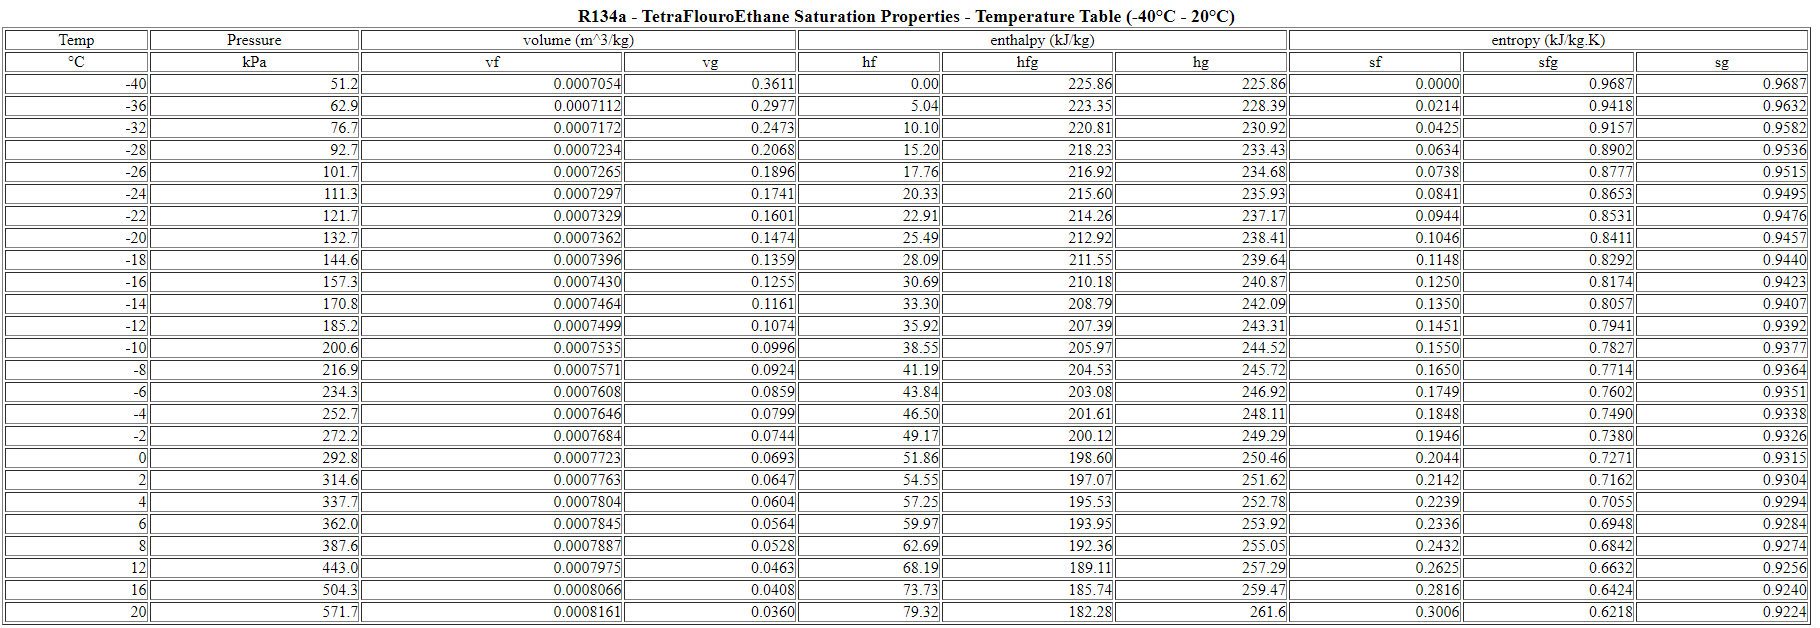

clc; clear all; format short

% r134a data - Nu antaget at være en ideal gas
R = 81.49 % Gaskonstant for r134a i J/(kg*K)

R = 81.4900

m = 1     % Antaget masse i liter

m = 1




% Stadie 1
% Indgang i kompressor
% Kølemiddelgassen r134a indsuges

p0 = 1    % Tryk før kompression

p0 = 1

t1 = 1    % Temperatur før kompression

t1 = 1

v1 = 1    % Volumeen før kompression

v1 = 1

h1 = 1    % Specifik entalpi før kompression

h1 = 1


% Stadie 2
% Kølemiddelgassen komprimes, antages for nu til at være adiabatisk -> 
% q12 = 0, altså ingen varme tilførsel til omgivelserne, men ikke tabsfrit
% w_diss > 0

p1 = 1    % Tryk efter kompression

p1 = 1

t2 = 1    % Temperatur efter kompression

t2 = 1

v2 = 1    % volumen efter kompression

v2 = 1

h2 = 1    % Specifik entalpi efter kompression

h2 = 1



% Trykændringsarbejde kompressoren laver
T = 1     % Konstant

T = 1


w12_p = m*R*T*log(p1/p0)

w12_p = 0


w12_v = m*R*T*log(v1/v2)

w12_v = 0

clc; clear all;

% Beholder volumen
slush = 1   % 1 liter

slush = 1

s_m3 = 0.001  % liter til m3

s_m3 = 1.0000e-03

r = 0.10/2    % radius på beholder

r = 0.0500

h_b = s_m3/(pi*r^2)

h_b = 0.1273


om_b = pi*r

om_b = 0.1571


% Rør størrelse
dy = 0.006

dy = 0.0060

di = 0.004

di = 0.0040


% Antal vindinger eller vendinger om beholderen
vind = h_b/dy           % Vi/endinger om rør

vind = 21.2207

ror_l = vind * om_b     % rørlængde i meter

ror_l = 3.3333


% indre rør volumen
v_i = di^2 * ror_l

v_i = 5.3333e-05


% Tryk fra coolpack ved -2 grader celsius
p = 2.72526*1e3

p = 2.7253e+03


m_i_ror = p*v_i

m_i_ror = 0.1453

ans = 2.7253e+03


% Entalpi for r134a
h1 = 220.4 * 1e3

h1 = 220400

h2 = 396.0 * 1e3

h2 = 396000



% Entalpi for slush
cV_slush = 3720       % J/(kg*K)

cV_slush = 3720

cV_r134 = 0.23901*1e3 % J/(kg*K)

cV_r134 = 239.0100

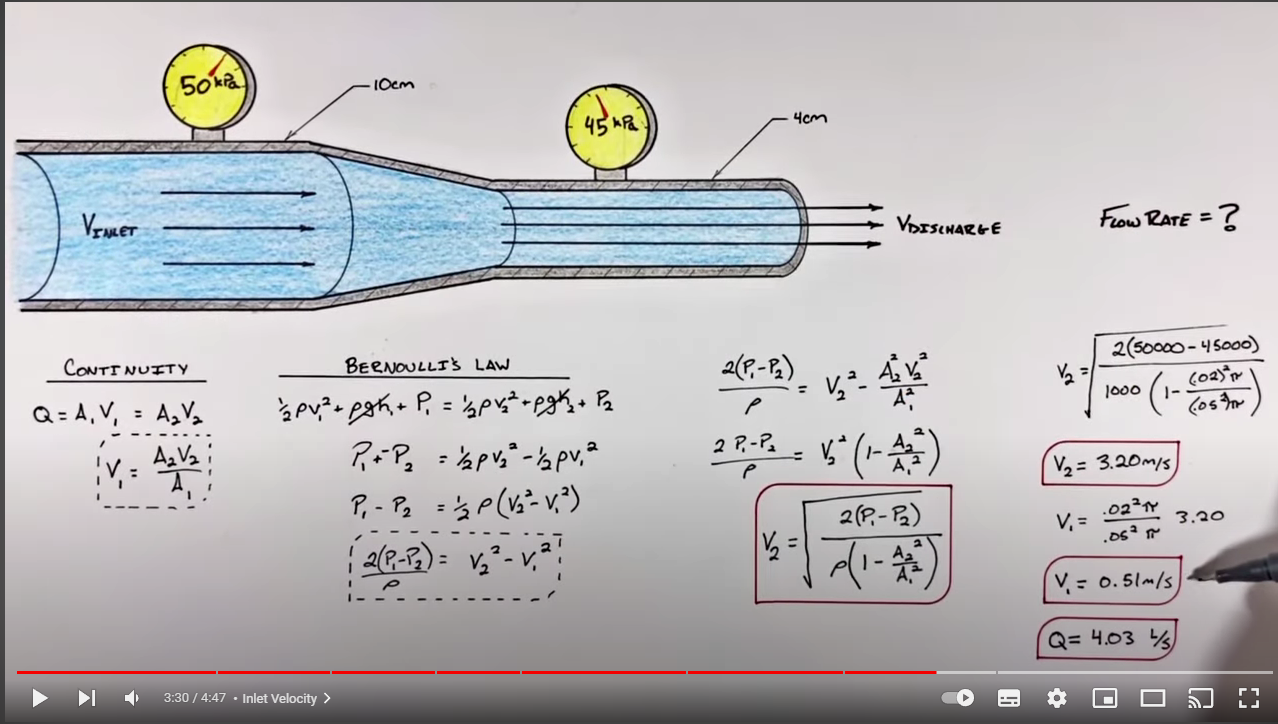

# Nye beregninger

clc; clear all;
u = symunit;

% Info for kompressor for datablad
Phi0 = 500 * u.W;
Vs = 16.15* u.cm^3;
n = 3000/u.min;


% Slagvolumenstrømmen
q_Vs = Vs*n;
q_Vs = vpa(unitConvert(q_Vs, u.m^3/u.h), 3)

$$q\_Vs = 2.91\,\frac{m^{3}}{h}$$



hs = [389.428 487.650 241.463 241.463] * u.kJ/u.kg;

vs = [0.150027, 0.025376] * u.m^3/u.kg; % volumenstrøm ved h1 og h2

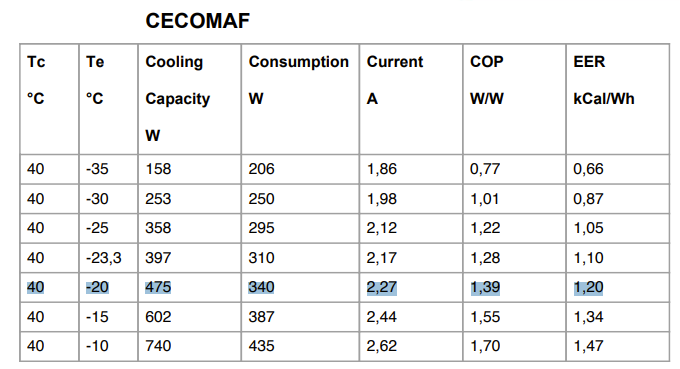

% Massestrøm
q_mr134a = Phi0/(hs(1) - hs(4));
q_mr134a = vpa(unitConvert(q_mr134a, "SI"), 3)

$$q\_mr134a = 0.00338\,\frac{\mathrm{kg}}{s}$$


% Indsugede volumenstrøm
q_v1 = q_mr134a * vs(1);
q_v1 = vpa(unitConvert(q_v1, "SI"),4)

$$q\_v1 = 0.000507\,\frac{m^{3}}{s}$$


% Volumenetrisk virkningsgrad
eta_v = q_v1/q_Vs;
vpa(unitConvert(eta_v, "SI"), 4)

$$ans = 0.6278$$


% Isentropisk effekt
Pis = q_mr134a*(hs(2) - hs(1));
Pis = vpa(unitConvert(Pis, u.kJ/u.kg), 3)

$$Pis = 0.332\,\frac{\mathrm{kJ}}{s}$$


% Isentropisk virkningsgrad
h_s2 = 429.04 * u.kJ/u.kg;
Pel = 266 * u.W; % Nominel cooling kapacity fra datablad
eta_s = Pis/Pel;

vpa(unitConvert(eta_s, "SI"), 3)

$$ans = 1.25$$


342/509

ans = 0.6719



h1 = 390.4 * u.kJ/u.kg;

h2s = 430.8 * u.kJ/u.kg

$$h2s = \frac{2154}{5}\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$

h2r = 489.8 * u.kJ/u.kg

$$h2r = \frac{2449}{5}\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$


eta_c = vpa(unitConvert((h2s - h1)/(h2r - h1),"SI"),3)

$$eta\_c = 0.406$$


% Virkningsgrad uf fra data fra CoolSelector
eta_c_CS = (417-390)/(489 - 390)

eta_c_CS = 0.2727

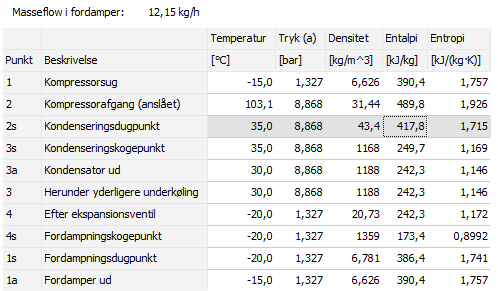

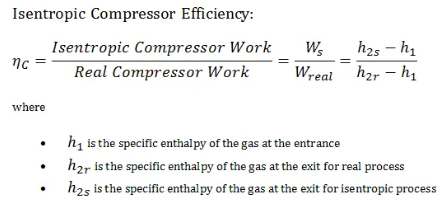

## Kondensator beregninger

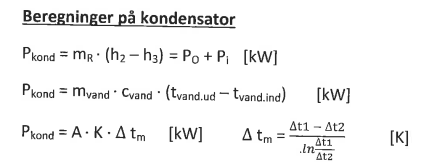

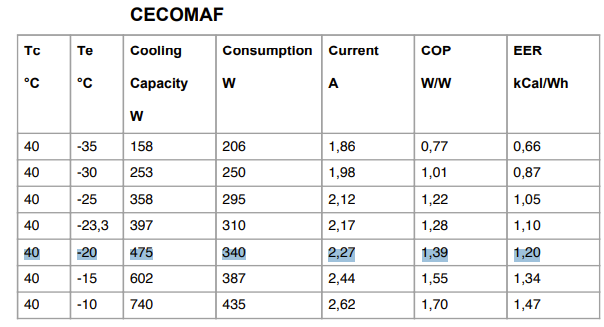

hs = [390.4 489.8 242.3 242.3] * u.kJ/u.kg;

Pkond = q_mr134a * (hs(2) - hs(3))

$$Pkond = 0.83634643327442859117581974714994\,\frac{\mathrm{kJ}}{s}$$

Pkond = vpa(unitConvert(Pkond, u.W),15)

$$Pkond = 836.346433274429\,W$$


vpa( hs(3) - hs(2))

$$ans = -247.5\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$


Pkond2 = (475 + 340) * u.W

$$Pkond2 = 815\,W$$

## Ventilberegninger

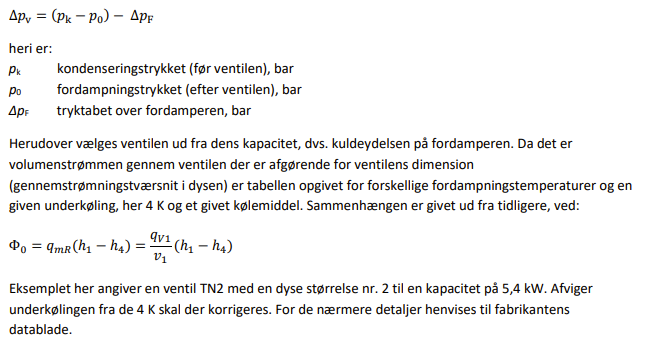

format longG

kelvin = 273.15;

pk = 8.868;
p0 = 1.327;
pf = 0;

pv = (pk - p0) - pf

pv =                      7.541



Tamb = 20;
T_Find = (kelvin + (-20)) * u.K;
T_Fud = (kelvin + (-15))*u.K;

R = 81.49 * u.J/(u.kg*u.K); % R134a gasconstant

p1 = 8.868 * u.bar;
p2 = 1.327 * u.bar;


v1 = R*T_Find/p1;
v2 = R*T_Find/p2;

v1 = vpa(unitConvert(v1,"SI"),3)

$$v1 = 0.0233\,\frac{m^{3}}{\mathrm{kg}}$$

v2 = vpa(unitConvert(v2,"SI"),3)

$$v2 = 0.155\,\frac{m^{3}}{\mathrm{kg}}$$

## Andre kompressor beregninger

clc; clear all;
u = symunit;

% Info fra opgaven
% kompressortab = 0.5 * u.kW;                 % Tab til omgivelser
Phi_41 = 0.5 * u.kW;         % Kuldeydelse på fordamperen
eta_komp = 0.8;                             % Isentrope el-virkningsgrad
eta_komp = 0.342/0.514;

h1 = 570.979 * u.kJ/u.kg;   % Entalpi i pkt 1
h2 = 640.003 * u.kJ/u.kg;   % Entalpi i pkt 2
h3 = 290.960 * u.kJ/u.kg;   % Entalpi i pkt 3
h4 = h3;                    % Entalpi i pkt 4


%% Opgave a og b %%

% Kompressor og specfik varmestrøm fra 4-1
q_41 = h1 - h4;

q_m = Phi_41/q_41;
q_m = vpa(unitConvert(q_m,"SI"),3)

$$q\_m = 0.00179\,\frac{\mathrm{kg}}{s}$$


% Tilførte eleffekt
h2s = 430 * u.kJ/u.kg;

wt_12 = (h2s - h1)/eta_komp;
el_effekt = wt_12*q_m;
el_effekt = vpa(unitConvert(el_effekt, u.kW), 3)

$$el\_effekt = -0.378\,\mathrm{kW}$$


% dKondensatorydelse
pkond = q_m * (h2 - h3);
pkond = vpa(unitConvert(pkond, u.kW), 3)

$$pkond = 0.623\,\mathrm{kW}$$


% COP - effektfaktor
COP = (Phi_41)/el_effekt;
COP = vpa(COP, 3)

$$COP = -1.32$$



%% Opgave c og d %%
eta_V = 0.85;                % Volumetrisk virkningsgrad
V = 17.3208 * u.m^3/u.h;      % Volumenstrøm fra coolpack
v1 = 0.134727 * u.m^3/u.kg;  % Specifik volumen


q_Vs = V/eta_V;
q_Vs = vpa(unitConvert(q_Vs,u.kg/u.h),3) % Slagvolumenstrøm

$$q\_Vs = 20.4\,\frac{m^{3}}{h}$$



Phi_0 = (q_Vs*eta_V/v1) * (h1 - h4);
Phi_0 = vpa(unitConvert(Phi_0, u.kW), 3)

$$Phi\_0 = 10.0\,\mathrm{kW}$$



COP = vpa(unitConvert(Phi_0/el_effekt, "SI"), 3)

$$COP = -26.4$$

# Fordamper beregninger

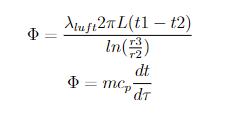

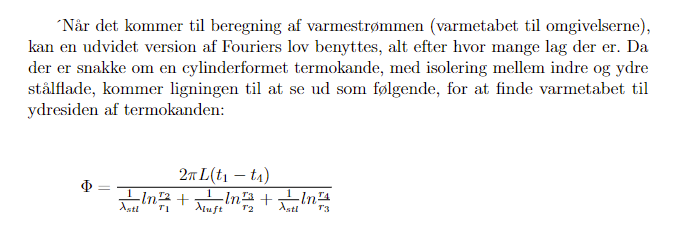

clc; clear all;
u = symunit;

% Gennemgang af eksempel 9.7 - med egne værdier

% Temperaturer
t1 = -20*u.K;    % Temp r134a
t2 = -10*u.K;    % Temp brine
t3 = 5*u.K;      % Temp medie
t4 = 20*u.K;     % Temp luft


% Beholder volumen
slush = 1   % 1 liter

slush = 1

s_m3 = 0.001 * u.m^3  % liter til m3

$$s\_m3 = \frac{1}{1000}\,m^{3}$$

r = 10*u.cm/2    % radius på beholder

$$r = 5\,\mathrm{cm}$$

h_b = s_m3/(pi*r^2)

$$h\_b = \frac{1}{25000\,\pi }\,\frac{m^{3}}{{\mathrm{cm}}^{2}}$$


om_b = pi*r

$$om\_b = 5\,\pi \,\mathrm{cm}$$


% Rør størrelse
dy = 24 * u.mm

$$dy = 24\,\mathrm{mm}$$

di = 10 * u.mm

$$di = 10\,\mathrm{mm}$$


% Antal vindinger eller vendinger om beholderen
vind = h_b/dy           % Vi/endinger om rør

$$vind = \frac{1}{600000\,\pi }\,\frac{m^{3}}{{\mathrm{cm}}^{2}\,\mathrm{mm}}$$

ror_l = vind * om_b     % rørlængde i meter

$$ror\_l = \frac{1}{120000}\,\frac{m^{3}}{\mathrm{cm}\,\mathrm{mm}}$$


% indre rør volumen
v_i = di^2 * ror_l

$$v\_i = \frac{1}{1200}\,\frac{m^{3}\,\mathrm{mm}}{\mathrm{cm}}$$



% Flowrate til hastighed
qm = 0.000507 * u.m^3/u.s;
A1 = pi * di^2/4

$$A1 = 25\,\pi \,{\mathrm{mm}}^{2}$$

v1 = qm/A1;
vi = vpa(unitConvert(v1, "SI"), 3)

$$vi = 6.46\,\frac{m}{s}$$


vi*di

$$ans = 64.553244917187839746475219726562\,\frac{m\,\mathrm{mm}}{s}$$


kin_abs = 0.0003462 * u.kg;


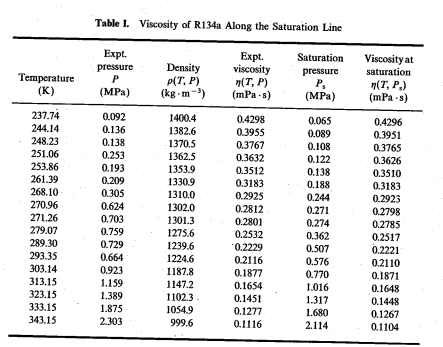

%testtesttest
clc; clear all;
u = symunit;

t = -20;                    % temp vi kigger på
v = 0.736 * u.dm^3/u.kg;    % specifik volumen ved temp
rho = 1/v;                  % specifik densitet ved temp
rho = vpa(unitConvert(rho, "SI"), 3)

$$rho = 1360.0\,\frac{\mathrm{kg}}{m^{3}}$$


% Fra tabellen
p = 0.193 * u.MPa;
ttab = (253.86 - 273.15) * u.K;
vis1 = 0.351 * u.mPa*u.s;
vis1 = vpa(unitConvert(vis1,"SI"), 3)

$$vis1 = 3.51e-4\,\frac{\mathrm{kg}}{m\,s}$$

rho = 1353.9 * u.kg/u.m^3;

% Kinematisk viskositet - passer fucking godt
kin_vis = vis1/rho;
kin_vis = vpa(unitConvert(kin_vis, "SI"), 3)

$$kin\_vis = 2.59e-7\,\frac{m^{2}}{s}$$


% Rør størrelse
dy = 24 * u.mm

$$dy = 24\,\mathrm{mm}$$

di = 10 * u.mm

$$di = 10\,\mathrm{mm}$$


% Flowrate til hastighed
Q1 = 0.000507 * u.m^3/u.s; 
A1 = pi * di^2/4

$$A1 = 25\,\pi \,{\mathrm{mm}}^{2}$$

v1 = Q1/A1;
vi = vpa(unitConvert(v1, "SI"), 3)

$$vi = 6.46\,\frac{m}{s}$$


Re = vi*di/kin_vis; % Reynolds tal
Re = vpa(unitConvert(Re, "SI"), 6)

$$Re = 248999.0$$

% Tallet ligger i intervallet 1 < Re < 1.000.000


% Varmeovergangstal
lambda = 0.1024 * u.W/(u.m*u.K); % ved t = -20C og p = 1.330 bar

% Prandls tal fra http://www.peacesoftware.de/einigewerte/r134a_e.html
cp = 1.293 * u.kJ/(u.kg*u.K);
eta = 337.2 * 1e-6 * u.Pa*u.s; % dynamisk viskositet

cp = unitConvert(cp, "SI")

$$cp = 1293\,\frac{m^{2}}{K\,s^{2}}$$

eta = unitConvert(eta, "SI")

$$eta = \frac{1555060525413715}{4611686018427387904}\,\frac{\mathrm{kg}}{m\,s}$$

lambda = unitConvert(lambda, "SI")

$$lambda = \frac{64}{625}\,\frac{\mathrm{kg}\,m}{K\,s^{3}}$$


Pr = eta*cp/lambda;
Pr = vpa(unitConvert(Pr, "SI"), 4)

$$Pr = 4.258$$




Prandl_fluid = 4.26;
Prandl_gas = 0.82;

% Formel 9.31 for Nusselt's tal bruges
C = 0.076;
m = 0.7;
n = 0.37;
Nu_m = C * Re^m * Prandl_fluid^n %* (Prandl_fluid/1)

$$Nu\_m = 778.09644081634783836639109016458$$

# Beregning af varmeovergangstal

Vi starte indefra ved slushice

newb

clc; clear all;
u = symunit;


% Data for slushice - antagede værdier for vand
rho = 999.8 * u.kg/u.m^3;
cp = 4.218 * u.kJ/(u.kg*u.K);
beta_v = -0.07 * 10^(-3) * 1/u.K;
lambda = 0.569 * u.W/(u.m*u.K);

eta = 3.8 * u.mPa * u.s; % Viskositet fra Chris - 20% sukker 80% vand 100% vand = 1.75
nu = 1.751 * 10^(-6) * u.m^2/u.s; % Kinematisk viskositet for vand

a = 0.131 * 10^(-6) * u.m^2/u.s; % Temperaturledetal

Prandtls_tal = 13;


% Data for cylinder - Beholder volumen
slush = 0.5;   % 1 liter
s_m3 = 0.0005 * u.m^3;  % liter til m3
D_beholder = 10 * u.cm;
r = D_beholder/2;    % radius på beholder
h_b = s_m3/(pi*r^2);
L = vpa(unitConvert(h_b, "SI"), 3) % højde på beholder

$$L = 0.0637\,m$$


c = 1 * u.km/u.h; % omrøringshastighed

% Data for temperaturer
tfl = -2;
tv_ori = -4;
tv1 =  -4.799;
delta_t = (tfl + tv1) * u.K;



% Konstanter
g = 9.81 * u.m/u.s^2;


% Beregningstal
Re = c*L/nu;
Re = vpa(unitConvert(Re, "SI"), 5)

$$Re = 10099.0$$


% Der er antaget temperaturer
Gr = g*L^3*beta_v*delta_t/(nu^2);
Gr = vpa(unitConvert(Gr, "SI"), 5)

$$Gr = 392900.0$$


Pr = eta*cp/lambda;
Pr = vpa(unitConvert(Pr, "SI"), 5)

$$Pr = 28.169$$


Ra = Gr*Pr;
Ra = vpa(unitConvert(Ra, "SI"), 7)

$$Ra = 11067720.0$$



% Beregnings af Nusselts tal v. turbulent strømning i slushice
% der antages en dynamisk viskositet ved væg temperatur

eta_v = eta * 2;
K1 = (eta/eta_v)^(0.14);
K2 = (1 + (D_beholder/L)^(2/3));


Nu = 0.0235 * (Re^(0.80) - 230) * (1.8 * Pr^(0.3) - 0.8)*K1*K2;
Nu = vpa(unitConvert(Nu, "SI"), 4)

$$Nu = 281.2$$



% Beregning af varmeovergangstal

alpha = Nu*lambda/L;
alpha = vpa(alpha, 4)

$$alpha = 2513.0\,\frac{W}{K\,m^{2}}$$


A1 = D_beholder * pi * L;
A1 = vpa(unitConvert(A1, "SI"), 5)

$$A1 = 0.02\,m^{2}$$



R1 = 1/(alpha*A1);
R1 = vpa(R1, 3)

$$R1 = 0.0199\,\frac{K}{W}$$

% Beregning af væg temp - ikke rigtig Phi, skal have fra chris mathcad
tfl = -2 * u.K;

h1 = 390.4 * u.kJ/u.kg;
h4 = 242.3 * u.kJ/u.kg;
qm_r134a = 0.00338 * u.kg/u.s

$$qm\_r134a = \frac{169}{50000}\,\frac{\mathrm{kg}}{s}$$


Phi = -qm_r134a* (h1 - h4);
Phi = vpa(unitConvert(Phi, u.W), 3)

$$Phi = -501.0\,W$$


syms tv

eq = 1/(alpha*A1) == (tfl - tv)/Phi;

tv = vpa(solve(eq, tv), 3)

$$tv = 3.34\,K$$




vpa(pi*D_beholder, 3)

$$ans = 31.4\,\mathrm{cm}$$

# Beregning til flow i rør - virker lovende

clc; clear all;
u = symunit;


% Data for r134a fra http://www.peacesoftware.de/einigewerte/calc_r134a.php7
rho = 1358.3 * u.kg/u.m^3;
cp = 1.293 * u.kJ/(u.kg*u.K);
beta_v = 2.27 * 10^(-3) * 1/u.K;
lambda = 102.4 *1e-3 * u.W/(u.m*u.K);

eta = 337.2 *1e-6 * u.Pa * u.s; % Viskositet 
nu = 2.37 * 10^(-6) * u.m^2/u.s; % Kinematisk viskositet for vand

a = 0.131 * 10^(-6) * u.m^2/u.s; % Temperaturledetal

Prandtls_tal = 13;

% Flowrate til hastighed for r134a
Q = 0.000507 * u.m^3/u.s; 
di = 10 * u.mm;
A = pi * di^2/4;
vi = Q/A;
vi = vpa(unitConvert(vi, "SI"), 3)

$$vi = 6.46\,\frac{m}{s}$$


% Data for cylinder - Beholder volumen
% slush = 0.5;   % 1 liter
% s_m3 = 0.0005 * u.m^3;  % liter til m3
% D_beholder = 10 * u.cm;
% r = D_beholder/2;    % radius på beholder
% h_b = s_m3/(pi*r^2);
L = di % højde på beholder

$$L = 10\,\mathrm{mm}$$


c = vi; % omrøringshastighed

% Data for temperaturer
tfl = -2;
tv = -4;
delta_t = (tfl + tv) * u.K;


% Konstanter
g = 9.81 * u.m/u.s^2;


% Beregningstal
Re = c*L/nu;
Re = vpa(unitConvert(Re, "SI"), 5)

$$Re = 26030.0$$


% Der er antaget temperaturer
Gr = g*L^3*beta_v*delta_t/(nu^2);
Gr = vpa(unitConvert(Gr, "SI"), 5)

$$Gr = -21724.0$$


Pr = eta*cp/lambda;
Pr = vpa(unitConvert(Pr, "SI"), 5)

$$Pr = 4.2578$$


Ra = Gr*Pr;
Ra = vpa(unitConvert(Ra, "SI"), 7)

$$Ra = -92497.26$$

% Beregnings af Nusselts tal v. turbulent strømning i slushice
% der antages en dynamisk viskositet ved væg temperatur

%eta_v = eta * 2;
%K1 = (eta/eta_v)^(0.14);
%K2 = (1 + (D_beholder/L)^(2/3));


Nu = 0.664*Re^(1/2)*Pr^(1/3)

$$Nu = 173.63208859137023398799604551118$$

Nu = vpa(unitConvert(Nu, "SI"), 4)

$$Nu = 173.6$$

% Beregning af varmeovergangstal

alpha = Nu*lambda/L;
alpha = vpa(unitConvert(alpha, u.W/u.K), 4)

$$alpha = 1778.0\,\frac{W}{K\,m^{2}}$$


% Passer ikke til inde i røret
% A1 = D_beholder * pi * L;
% A1 = vpa(unitConvert(A1, "SI"), 5)
% 
% 
% R1 = 1/(alpha*A1);
% R1 = vpa(R1, 3)